Aerofoil

## **Aerofoil shape**

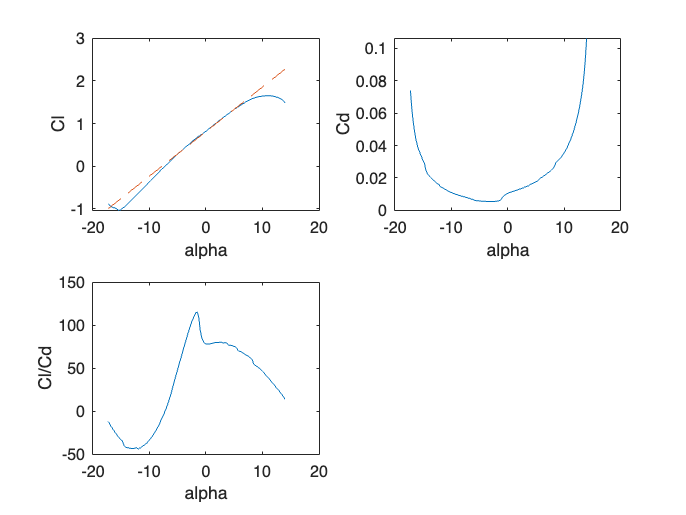

airfoil = Airfoil();
airfoil = airfoil.readPolar("xf-sc21010-il-1000000.csv");
airfoil = airfoil.readShape("sc21010.dat.txt");
airfoil = airfoil.interpShape(9);
figure(1)
clf;
airfoil.plotPolar()

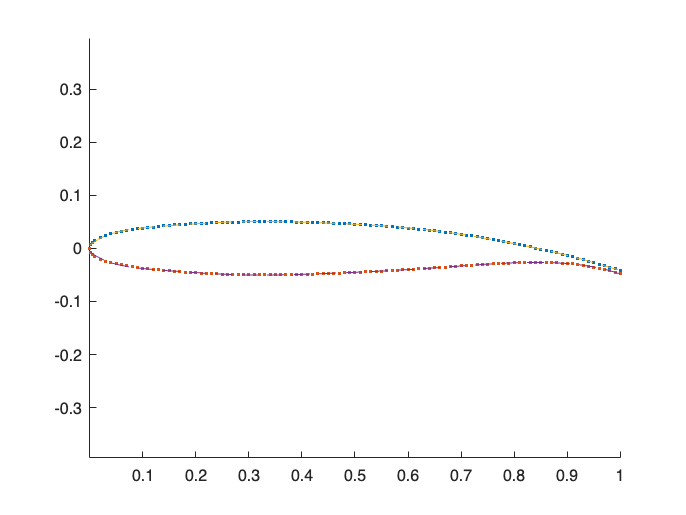


figure(2)
clf;
airfoil.plotShape()


airfoil

airfoil =   Airfoil with properties:

            alpha: [125×1 double]
               Cl: [125×1 double]
               Cd: [125×1 double]
               Cm: [125×1 double]
       uppershape: [103×2 double]
       lowershape: [103×2 double]
    upperShapefun: @(x_c)polyval(p_upper,x_c)
    lowerShapefun: @(x_c)polyval(p_lower,x_c)
              x_c: [0 0.0020 0.0040 0.0060 0.0080 0.0100 0.0120 0.0140 0.0160 0.0180 0.0200 0.0220 0.0240 0.0261 0.0281 0.0301 0.0321 0.0341 0.0361 0.0381 0.0401 0.0421 0.0441 0.0461 0.0481 0.0501 0.0521 0.0541 0.0561 0.0581 0.0601 … ] (1×500 double)
           t_cfun: @(x_c)polyval(p_thickness,x_c)
              t_c: 0.1007
             x_cm: 0.3246
               a0: 6.0019
                b: 0.8102
        alphaSPos: 0.1920
        alphaSNeg: -0.2662


Wing Definition:

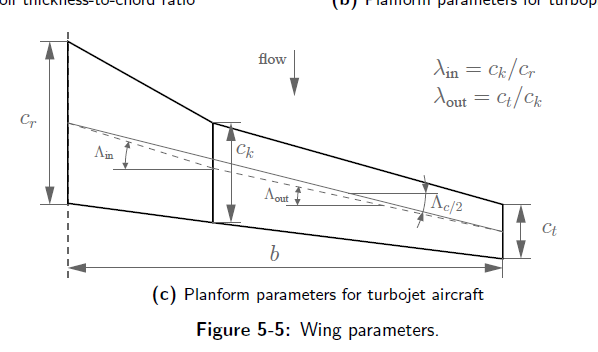

Define wing:

wing = WingGeometry();
wing.cr = 4.9;
wing.ck = 3.5;
wing.ct = 1.5;
wing.s = 28.45/2;
wing.Lambdain50 = 0*pi/180;
wing.Lambdaout50 = 0*pi/180;
wing.yk = 5.69;
wing = wing.calcSref()

wing =   WingGeometry with properties:

             cr: 4.9000
             ck: 3.5000
             ct: 1.5000
              s: 14.2250
             yk: 5.6900
     Lambdain50: 0
    Lambdaout50: 0
              N: []
             Sc: []
         stripy: []
             AR: 8.9465
            Sin: 47.7960
           Sout: 42.6750
           cbar: 3.3500
              b: 28.4500
           SREF: 90.4710
      twist_max: []
             cn: []
       twistfun: @(y)obj.twist_max-obj.twist_max./obj.s.*abs(y)
             dY: []


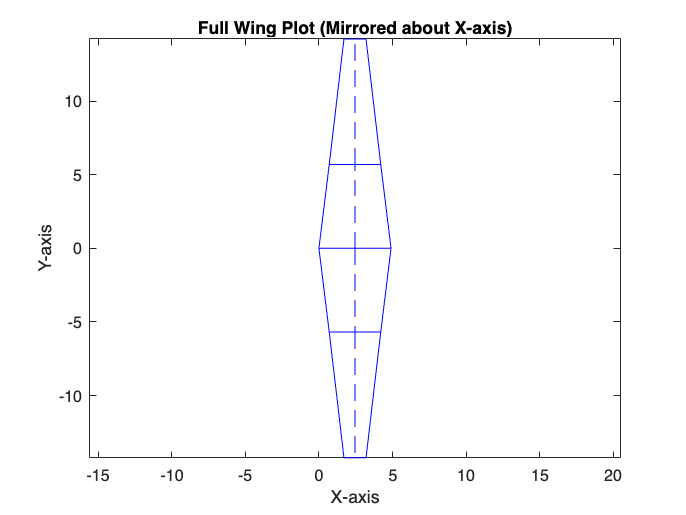

wing.N = 31;
figure(3)
clf;
axis equal
wing.plotWing()

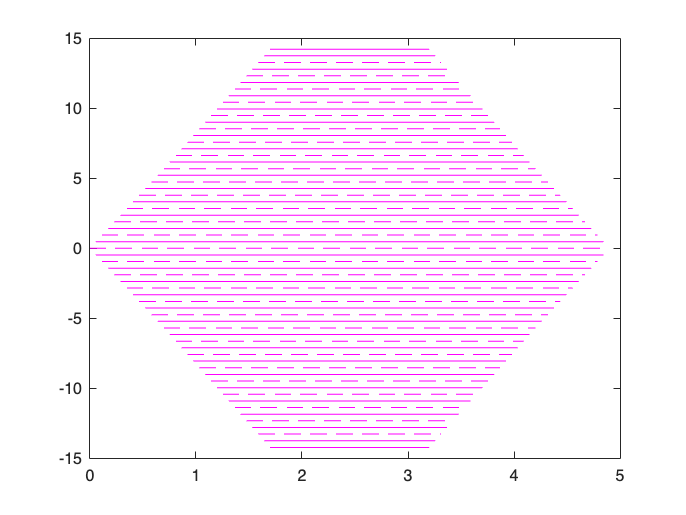

wing.c_at_y(10);
wing = wing.createStrips();
wing.plotStrips();

wing = wing.calcSc()

wing =   WingGeometry with properties:

             cr: 4.9000
             ck: 3.5000
             ct: 1.5000
              s: 14.2250
             yk: 5.6900
     Lambdain50: 0
    Lambdaout50: 0
              N: 31
             Sc: [0.7376 1.6332 1.8440 2.0547 2.2655 2.4762 2.6869 2.8977 3.1084 3.3218 3.5404 3.7617 3.9830 4.2043 4.4256 4.5362 4.4256 4.2043 3.9830 3.7617 3.5404 3.3218 3.1084 2.8977 2.6869 2.4762 2.2655 2.0547 1.8440 1.6332 0.7376]
         stripy: [-14.2250 -13.2767 -12.3283 -11.3800 -10.4317 -9.4833 -8.5350 -7.5867 -6.6383 -5.6900 -4.7417 -3.7933 -2.8450 -1.8967 -0.9483 0 0.9483 1.8967 2.8450 3.7933 4.7417 5.6900 6.6383 7.5867 8.5350 9.4833 10.4317 11.3800 12.3283 13.2767 14.2250]
             AR: 8.9465
            Sin: 47.7960
           Sout: 42.6750
           cbar: 3.3500
              b: 28.4500
           SREF: 90.4710
      twist_max: []
             cn: [1.5000 1.7222 1.9444 2.1667 2.3

Cruise Condition

%Chord length
c = wing.cbar;
cruise = AirCondition()

cruise =   AirCondition with properties:

      M: []
      V: []
      h: []
    rho: []
      T: []
      a: []
      P: []
     nu: []
     mu: []
     Re: []


cruise.M = 0.8;
cruise.h = convlength(39000, 'ft','m');
cruise = cruise.init(wing.cbar)

cruise =   AirCondition with properties:

      M: 0.8000
      V: 236.0557
      h: 1.1887e+04
    rho: 0.3164
      T: 216.6500
      a: 295.0696
      P: 1.9677e+04
     nu: 4.4930e-05
     mu: 1.4216e-05
     Re: 1.7600e+07


## Lifting Line Theory

[CLclean, CDi, Cly] = LLE_new(wing,airfoil,cruise,0,40,1e-2)

Unrecognized function or variable 'alpha'.

Error in LLE_new (line 63)
        alphae = alpha - alpha_induced;

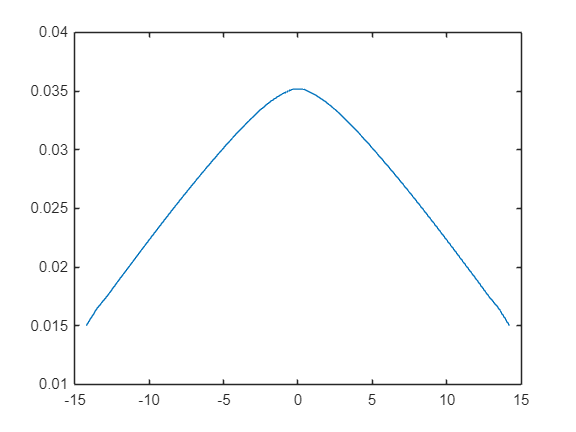

Swet_SrefWing = 2.2;
Swet_SrefBody = 5;
l_d = 10;
figure(2)
clf;
plot(Cly(1,:),Cly(2,:))

## Drag Model, Ref15

## Friction Drag

CDF = CDFfun(cruise.M, cruise.Re, wing, airfoil.x_cm, airfoil.t_c, l_d, Swet_SrefWing, Swet_SrefBody)

CDF = 0.0169

## Wave Drag

Integration of drag produced by each strip gives the total wave drag coefficient

CDW = CDWfun(wing,Cly,cruise.M,airfoil.t_c)

CDW = 2.5925e-04

Total Drag

CDtotal = CDF + CDW + CDi

CDtotal = 0.0256

L_D = CLclean/CDtotal

L_D = 29.4092

## Wing Weight

W_crew = 500 * 82.8;                     % Passenger weight + carry-on luggage (kg) % Ref 04 p.45
W_crew = W_crew + (12 + 4) * 79.4;       % Crew weight + carry-on luggage (kg)      % Roskam Part I p.8
W_payload = 500 * 17;                    % Passener checked luggage (kg)            % Ref 04 p.45
W_payload = W_payload + (12 + 4) * 13.6; % Crew checked luggage (kg)                % Roskam Part I p.8
Wpay = 9.81*(W_crew + W_payload)

Wpay = 5.0412e+05

Wto = 4.3895*1e5*9.81

Wto = 4.3061e+06

nult = 3.75; %Chatgpt, b777
range = convlength(7500, 'naut mi','m');

Ww = wingWeightLTH(wing,airfoil.t_c,Wto)

Ww = 3.3437e+05

%Ww = wingWeightHowe(wing,Wpay,Wto,nult,t_c,V,range*1e03)
mw = Ww/9.81 %one wing

mw = 3.4085e+04

## Performance

h_cruise2 = convlength(18000, 'ft','m');
[T_65, c_65, P_65, rho_65] = atmosisa(h_cruise2);
M_cruise2 =  convvel(400, 'kts', 'm/s')/c_65;
C_cruise = 0.5 ./ 3600;
[W_f_0, W_i] = Wf_W0(cruise.h, h_cruise2, cruise.M, M_cruise2, L_D, C_cruise)

W_f_0 = 0.3285

W_i =     0.9700    0.9850    0.7480    0.9900    0.9931    0.9826    0.9899    0.9954    0.9920



OPTindex = W_f_0*Ww %index to minimize

OPTindex = 1.0983e+05